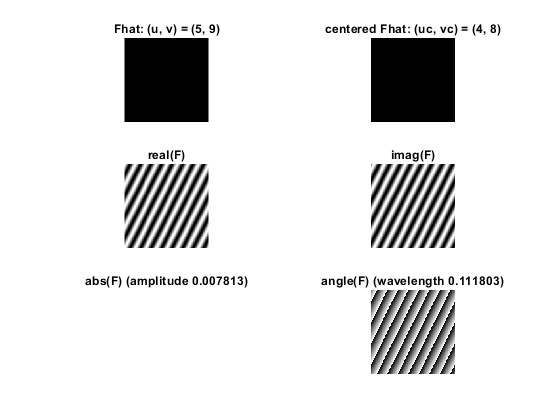

fftwave(5, 9, 128)

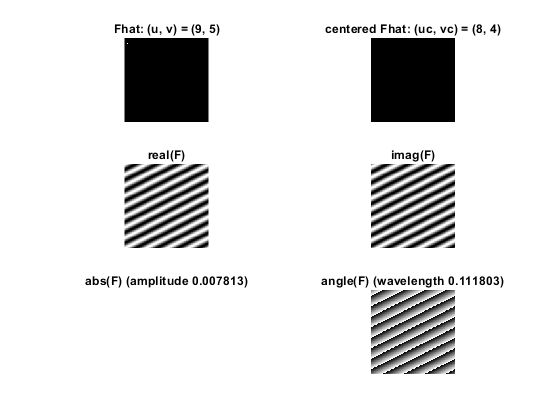

fftwave(9, 5, 128)

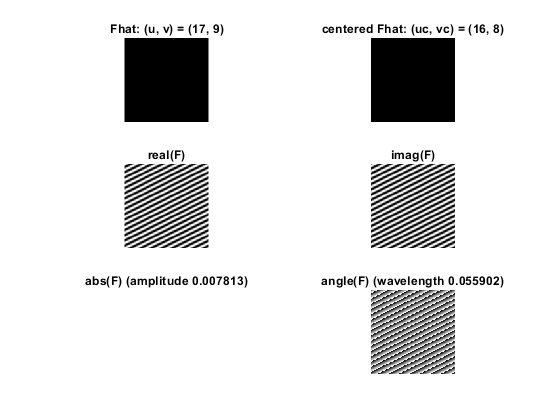

fftwave(17, 9, 128)

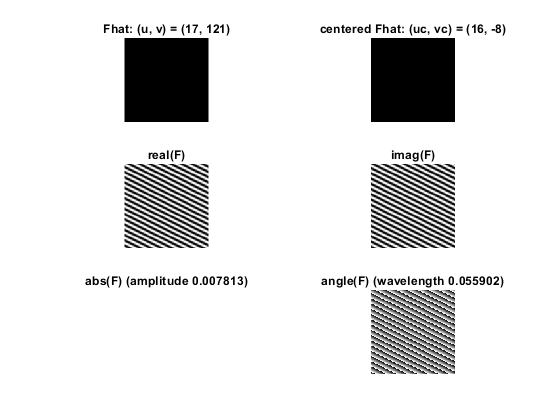

fftwave(17, 121, 128)

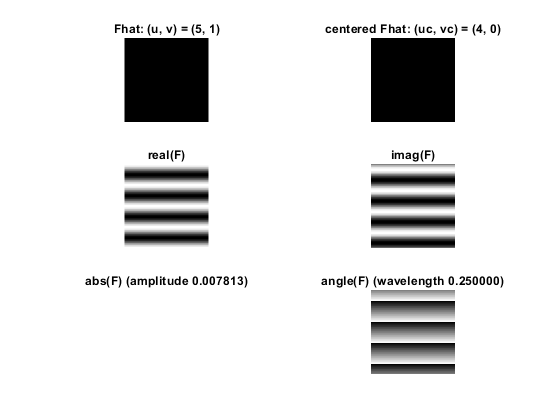

fftwave(5, 1, 128)

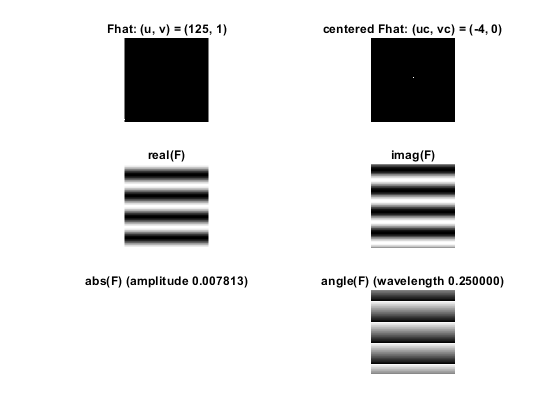

fftwave(125, 1, 128)

% Q 7-9
close all
F = [ zeros(56, 128); ones(16, 128); zeros(56, 128)];
G = F';
H = F + 2 * G;

Fhat = fft2(F);
Ghat = fft2(G);
Hhat = fft2(H);

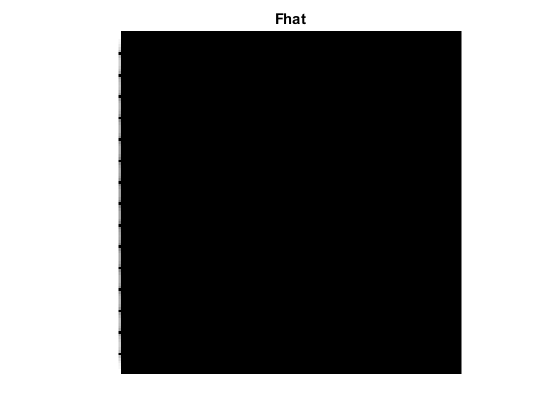

showgrey(log(1 + abs(Fhat)))
title('Fhat')

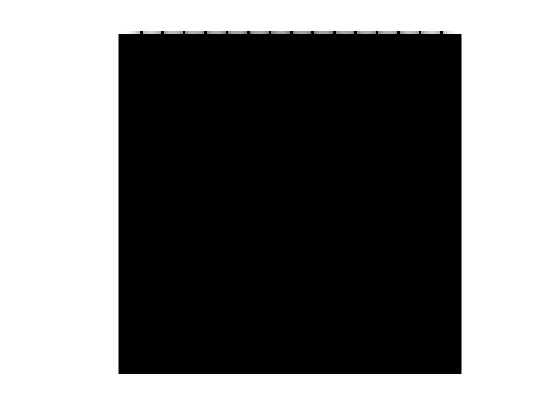

showgrey(log(1 + abs(Ghat)));

title('Ghat')

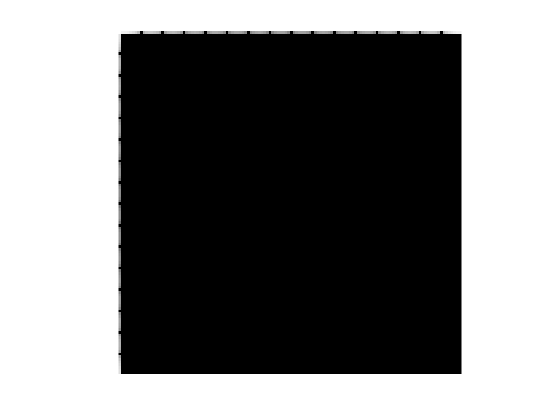

showgrey(log(1 + abs(Hhat)));

title('Hhat')

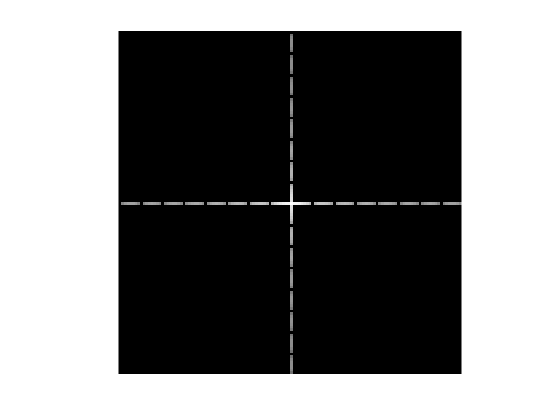


showgrey(log(1 + abs(fftshift(Hhat))));

title('Hhat centered')

% Q 10
disp("Question 10")

    "Question 10"



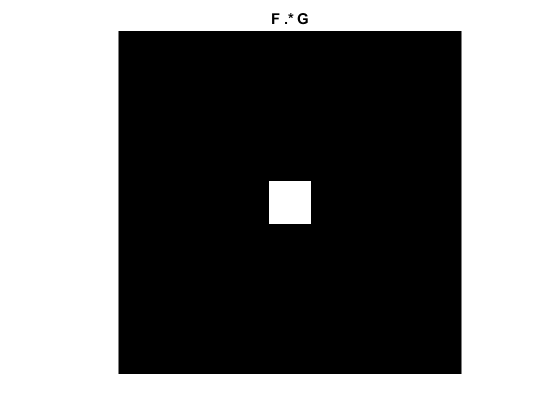

sz = 128;

showgrey(F .* G);
title('F .* G')

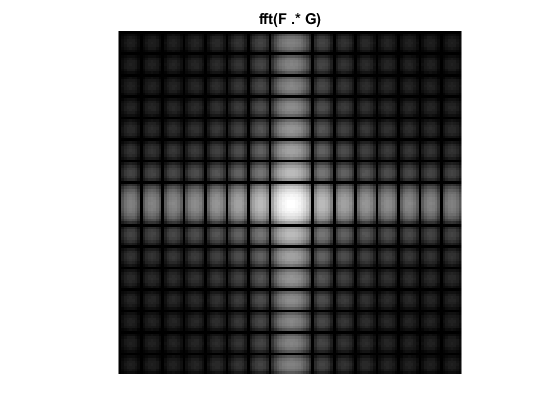


showfs(fft2(F .* G));
title('fft(F .* G)')

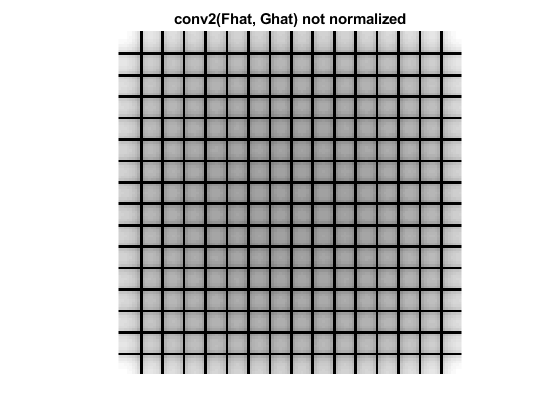

%FGhat = conv2(ftshift(fFhat), fftshift(Ghat));
Fhat_shifted = fftshift(Fhat);
Ghat_shifted = fftshift(Ghat);

% same padding to get central part that's the same size
FGhat = conv2(Fhat_shifted, Ghat_shifted, "same");
showfs(FGhat);
title('conv2(Fhat, Ghat) not normalized')

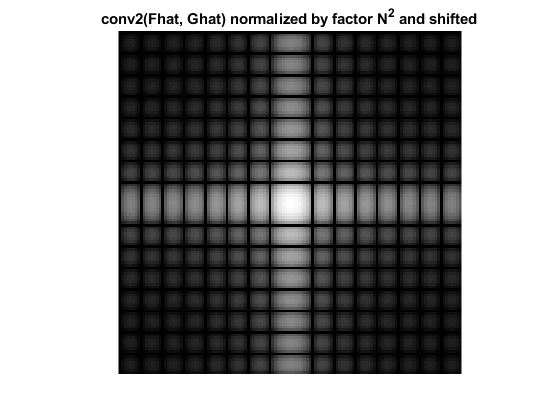

showfs(fftshift(FGhat / sz.^2));
title('conv2(Fhat, Ghat) normalized by factor N^2 and shifted')

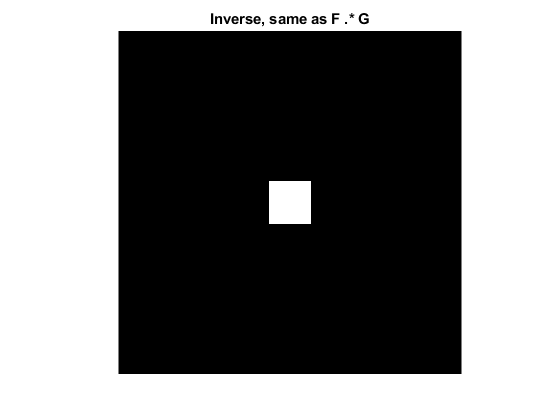

showgrey(abs(ifft2(FGhat)));
title('Inverse, same as F .* G')

% Q 11
disp("Question 11")

Question 11


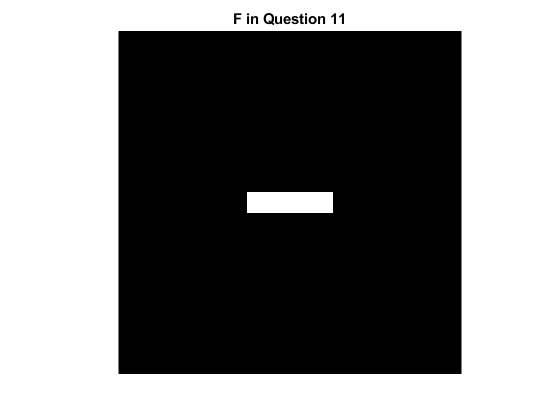

F = [zeros(60, 128); ones(8, 128); zeros(60, 128)] .* ...
[zeros(128, 48) ones(128, 32) zeros(128, 48)];
showgrey(F);
title("F in Question 11")

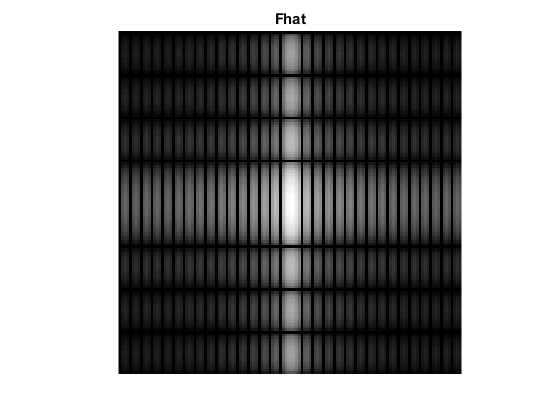


showfs(fft2(F));
title("Fhat")